%Battery current controller
V_dc=48;
C=440e-6;
R=23; %46
L_batt=2.3e-3;
D_batt=0.5;
s = tf('s');
Gbitod=(((s*V_dc*C)+(2*V_dc/R)))/((s^2*L_batt*C)+(s*(L_batt/R))+(1-D_batt)^2)

Gbitod =
 
         0.02112 s + 4.174
  -------------------------------
  1.012e-06 s^2 + 0.0001 s + 0.25
 
Continuous-time transfer function.
Model Properties


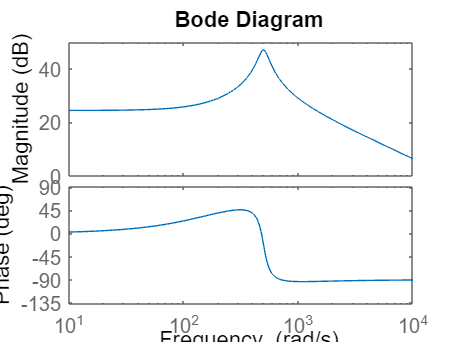

bode(Gbitod);

%margin(Gbitod);
%controlSystemDesigner(Gbitod);
%kp=0.65;
%ki=220;
%Gkp=(s*kp+ki)/(s);
%Gtotal=Gbitod*Gkp;
%bode(Gtotal);
%margin(Gtotal);
% Plot Bode plot for both systems on the same figure
%figure;
%bode(Gbitod); % plot first system
%hold on;    % hold the current plot
%bode(Gtotal); % plot second system
%hold off;   % release the hold
% Optional: add legend to identify systems
%legend('uncompensated', 'compensated');
